# PRACTICA 1

# Ejercicio 1.1

En la primera parte del ejercicio vamos a cargar, escuchar y visualizar las señales

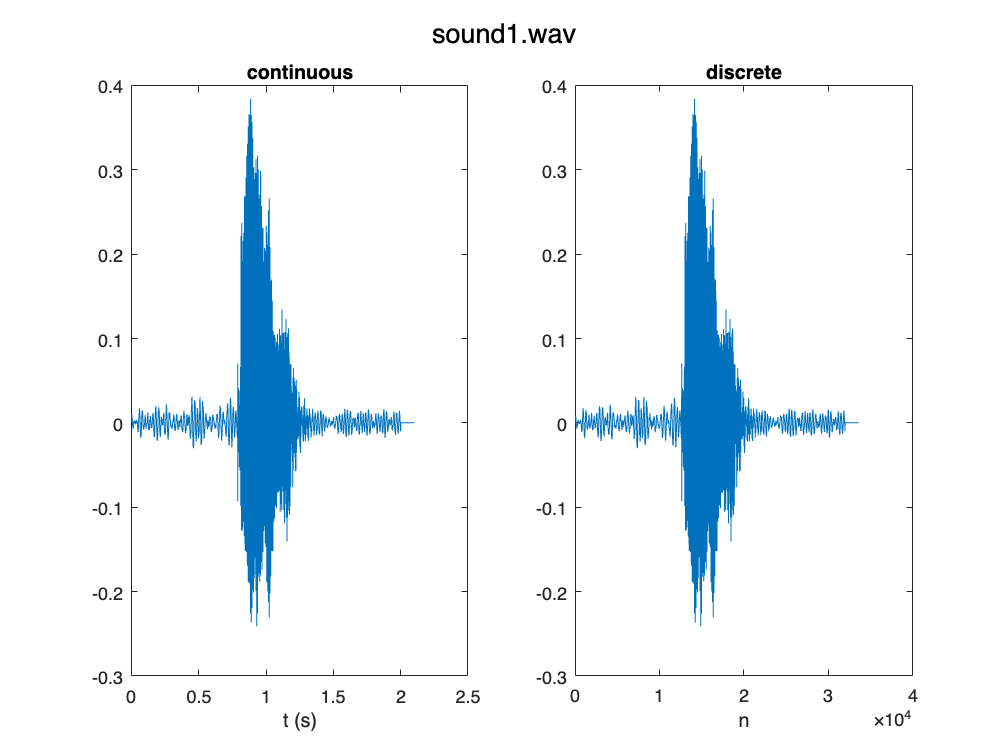

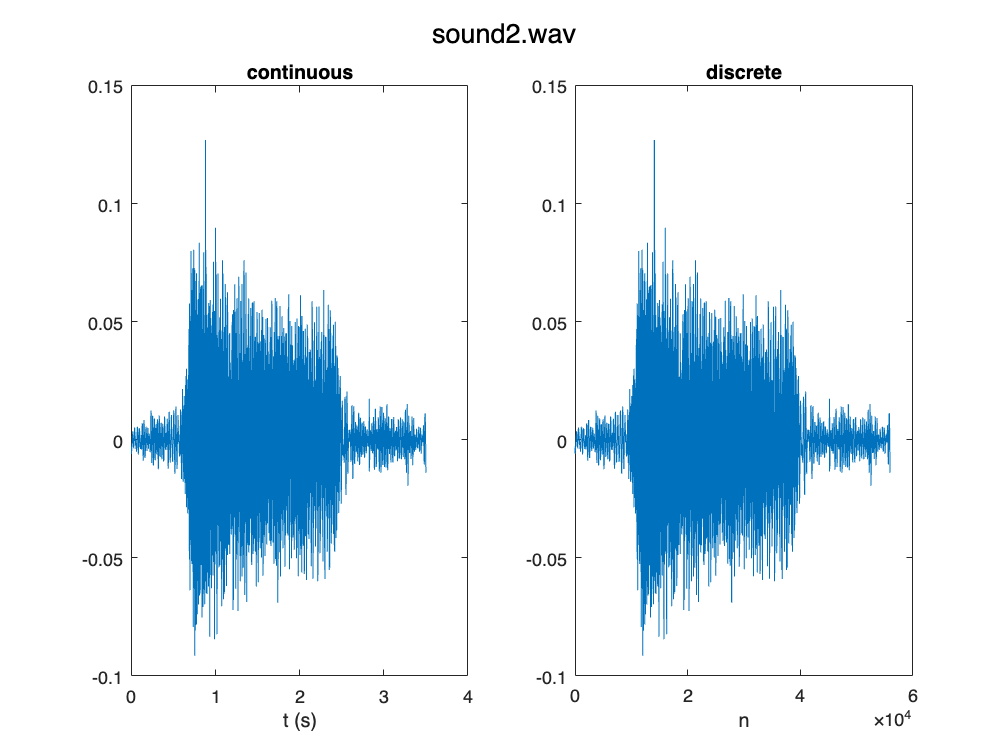

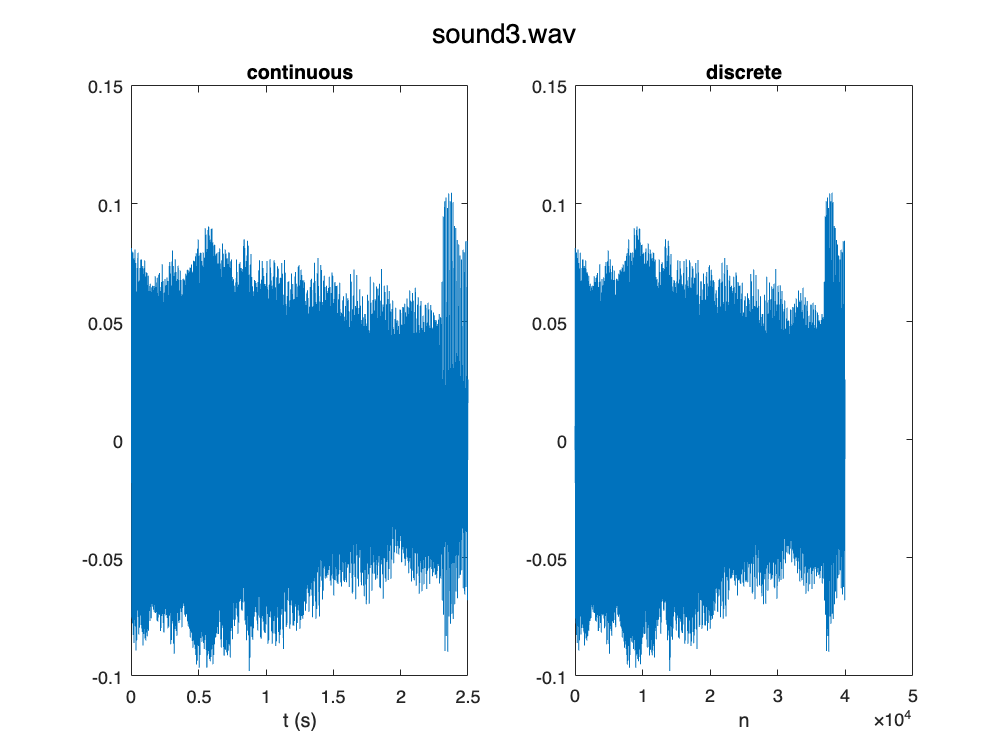

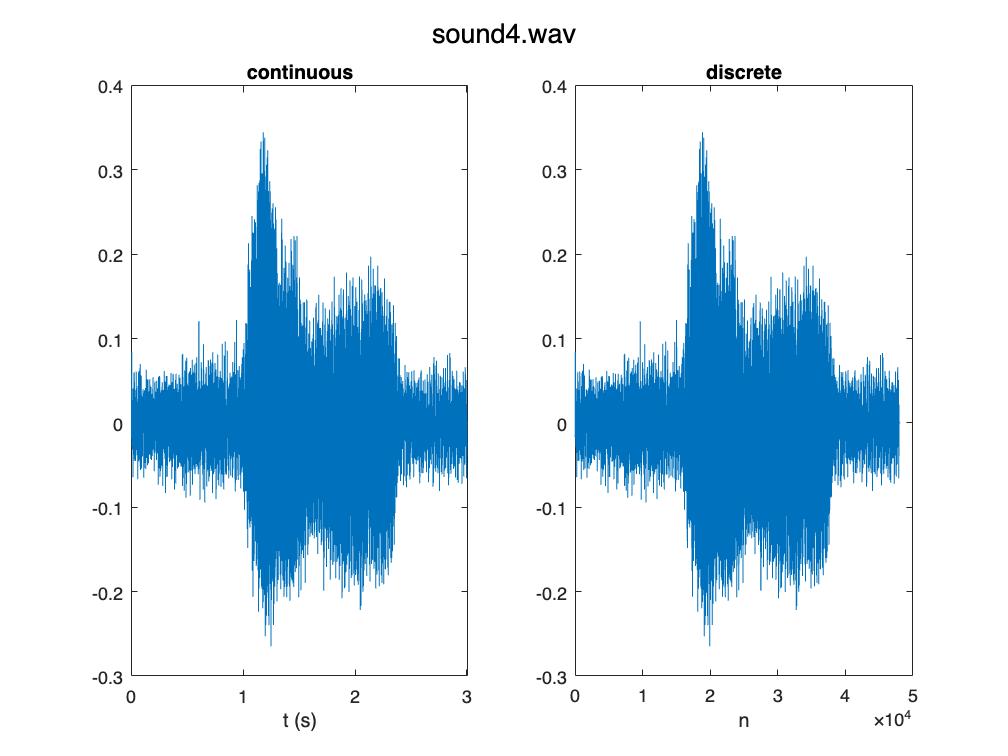

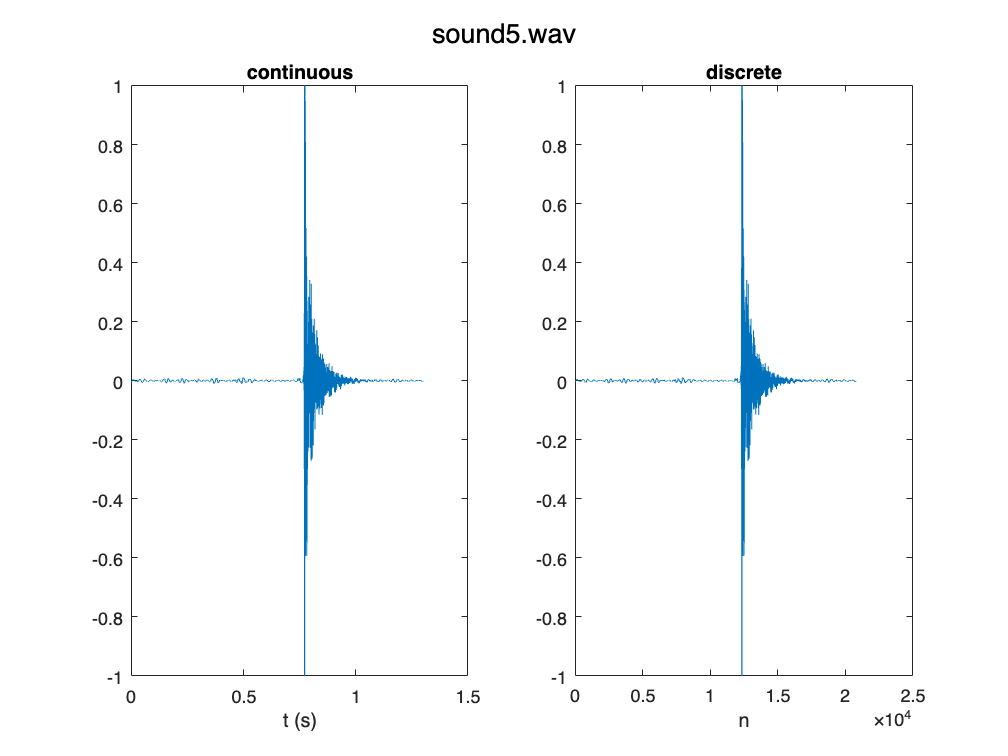

sound_files = dir('../audio/*.wav');

for file = 1:length(sound_files)
    file_path = strcat('../audio/', sound_files(file).name);
    [y, fs] = audioread(file_path);

    figure
    sgtitle(sound_files(file).name)

    subplot(1, 2, 1)
    dibuja(y, fs)
    title("continuous")

    subplot(1, 2, 2)
    plot(y)
    title("discrete")
    xlabel("n")


    % sound(y, fs)
    % pause(5)
end

# Ejercicio 1.2

En este ejercicio y el siguiente usaremos solo los sonidos almacenados en y1, y2 e y3. 

Crea los vectores yframe1, yframe2 e yframe3 de forma que cada uno de ellos contenga **un tramo de 100ms** de la señal correspondiente **en donde aparezca sonido**. 

Dibújalos en figuras independientes con el eje temporal en segundos (usa dibuja.m)

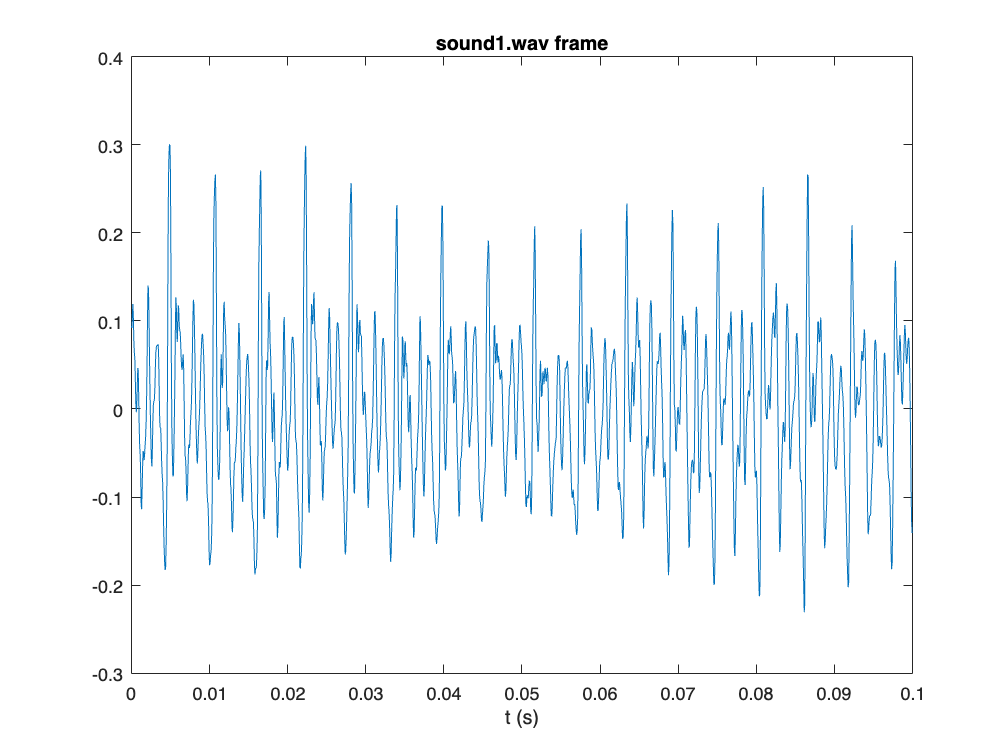

[y1, fs1] = audioread('../audio/sound1.wav');
[y2, fs2] = audioread('../audio/sound2.wav');
[y3, fs3] = audioread('../audio/sound3.wav');
[y4, fs4] = audioread('../audio/sound4.wav');
[y5, fs5] = audioread('../audio/sound5.wav');

L_frame1 = round(0.1*fs1);
L_frame2 = round(0.1*fs2);
L_frame3 = round(0.1*fs3);

L_duration1 = 512/fs1;
L_duration2 = 512/fs2;
L_duration3 = 512/fs3;

yframe1 = y1(15000:15000 + L_frame1);
yframe2 = y2(14000:14000 + L_frame2);
yframe3 = y3(1000:1000 + L_frame3);

figure
dibuja(yframe1, fs1);
title('sound1.wav frame');

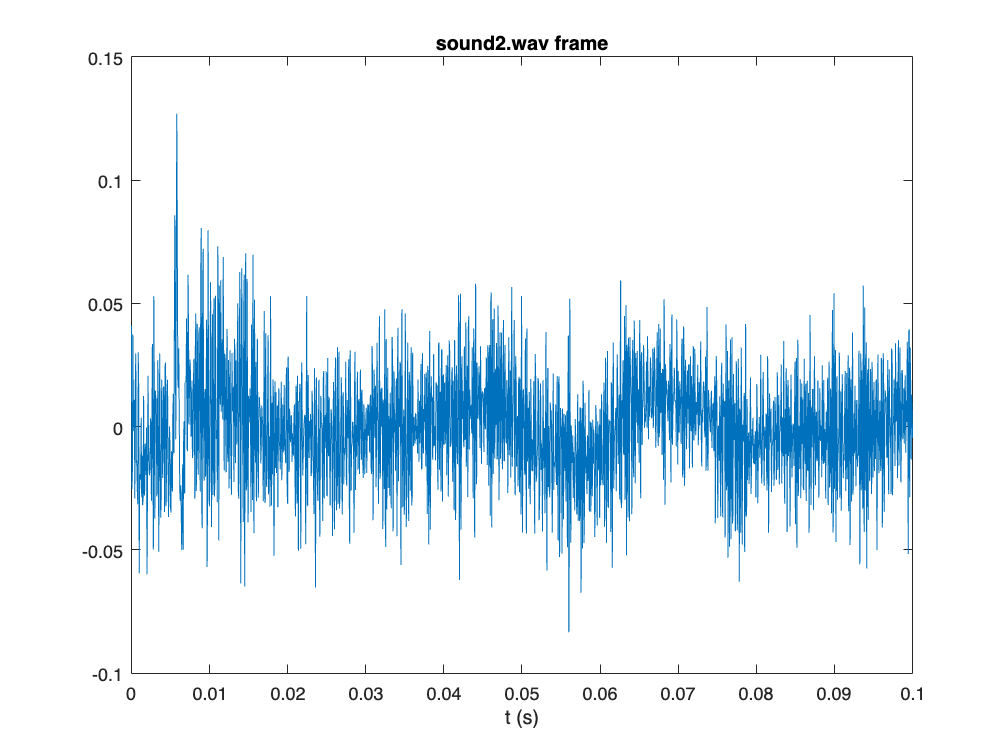

dibuja(yframe2, fs2);
title('sound2.wav frame');

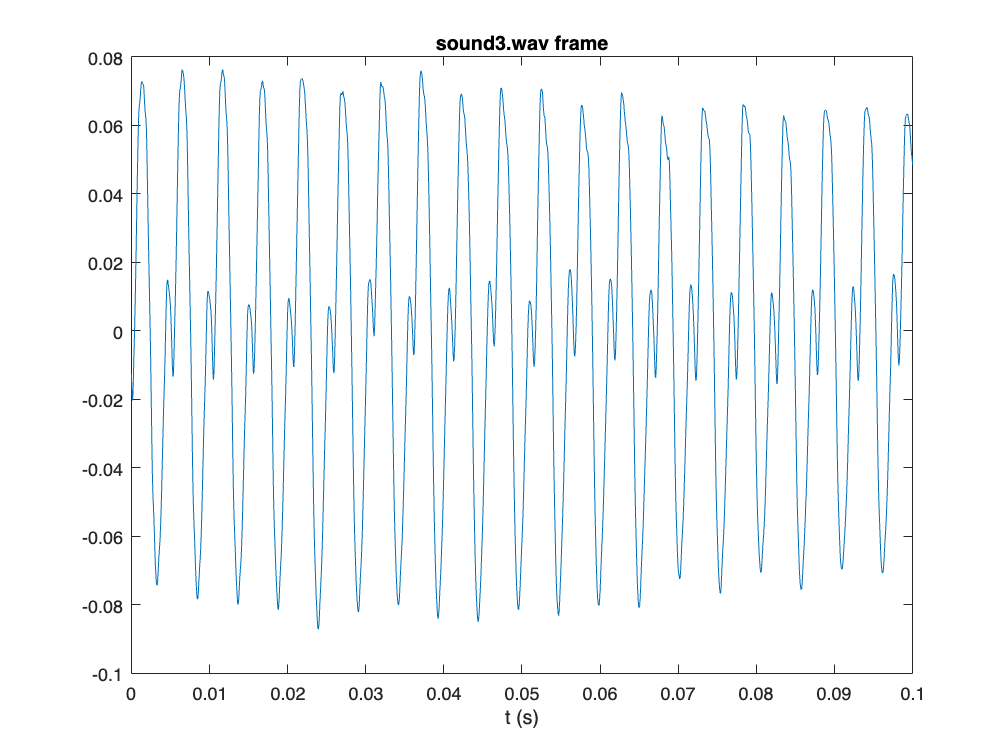

dibuja(yframe3, fs3);
title('sound3.wav frame');

¿Cuáles tienen estructura periódica? A partir de lo que ves, estima cuál es el periodo fundamental de las que son periódicas, T, y calcula su frecuencia fundamental, f0, como el inverso de T. Explica brevemente como has hecho los cálculos.

Calcula la potencia media y la energía  de las señales y1, y2, y3

P1 = mean(y1 .^ 2)

P1 = 0.0014

P2 = mean(y2 .^ 2)

P2 = 2.3102e-04

P3 = mean(y3 .^ 2)

P3 = 0.0018

E1 = sum(y1 .^ 2)

E1 = 45.9239

E2 = sum(y2 .^ 2)

E2 = 12.9372

E3 = sum(y3 .^ 2)

E3 = 70.5178

# Ejercicio 1.3

En este ejercicio vamos a realizar el **procesado digital de las señales por tramas**. Para ello vamos a realizar una funcion que descomponga una señal en tramas sin solape empleando la funcion de matlab **reshape**. En caso de que el número de muestras de la señal no sea un múltiplo entero de la longitud de la trama deberás rellenar con ceros la señal **previamente**. 

En esta funcion NO PUEDES EMPLEAR BUCLES

La cabecera de la funcion será la siguente:

El resultado de la funcion es una matriz en la que cada columna contiene las muestras de cada trama. **Escribe al final de este livescript el código de la función.**

Una vez descompuesta una señal en tramas, **se puede visualizar cómo varía su energía en el tiempo** calculando la energía de sus tramas (para ellos usa la función sum). El resultado para cada señal será **un vector E **cuya longitud será el número de tramas y en cada elemento tendremos la energia de cada trama.

La longitud de cada vector E es distinta para cada señal porque los sonidos también tienen distinta duración. Se pueden dibujar vectores de distinta longitud en una misma figura usando el comando hold. Busca en la documentación de Matlab como se usa hold y dibuja las tres energías en una misma figura con un eje de tiempos discreto. Comenta la diferencia entre ellas.

E1_frames = sum(tramas_sin_solape(y1, fs1, 0.1) .^ 2)

E1_frames =     0.0856    0.1295    0.1558    0.0603    0.3266    0.2271    0.1244    0.4253   14.4187   14.7852    8.6362    5.1438    0.7147    0.1323    0.0543    0.1039    0.1041    0.1050    0.1092    0.0817    0.0001


E2_frames = sum(tramas_sin_solape(y2, fs2, 0.1) .^ 2)

E2_frames =     0.0147    0.0261    0.0404    0.0561    0.0569    0.0797    0.2464    1.0637    1.0944    0.8706    0.8499    0.6652    0.7540    0.6237    0.6010    0.5256    0.4334    0.6498    0.4959    0.4557    0.5391    0.5557    0.7049    0.4736    0.3875    0.1610    0.0882    0.0445    0.0463    0.0945    0.0768    0.0431    0.0594    0.0243    0.0350


E3_frames = sum(tramas_sin_solape(y3, fs3, 0.1) .^ 2)

E3_frames =     3.8681    3.3250    3.3114    3.2730    3.8555    4.2803    4.0105    3.5335    3.5332    3.3567    3.5607    3.2982    3.0752    2.6168    2.2542    2.0346    1.9557    1.8406    1.9668    1.4414    1.6542    1.8239    1.7027    2.9137    2.0316


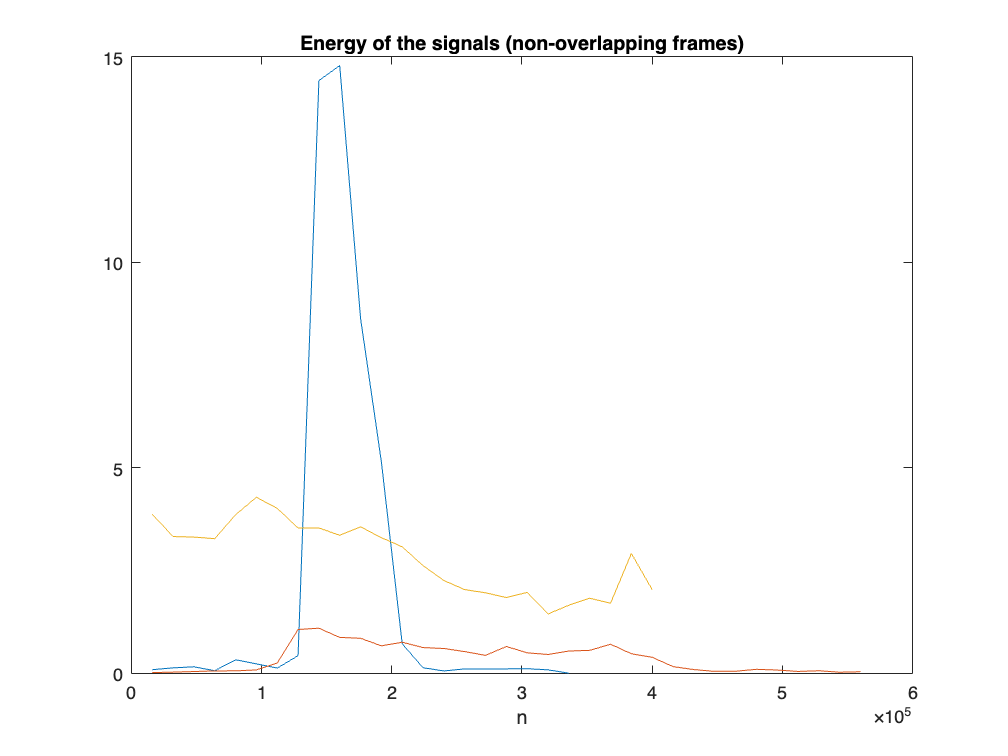

plot((1:length(E1_frames)) * fs1, E1_frames);
hold on
plot((1:length(E2_frames)) * fs2, E2_frames);
plot((1:length(E3_frames)) * fs3, E3_frames);
title('Energy of the signals (non-overlapping frames)');
xlabel('n');
hold off

A continuación representaremos los vectores de energía empleando tiempo continuo con la función dibuja que has programado anteriormente. Recuerda que  el tiempo entre tramas es 100 ms, por lo que tienes que crear un eje de tiempos en segundos distinto del usado para los sonidos.

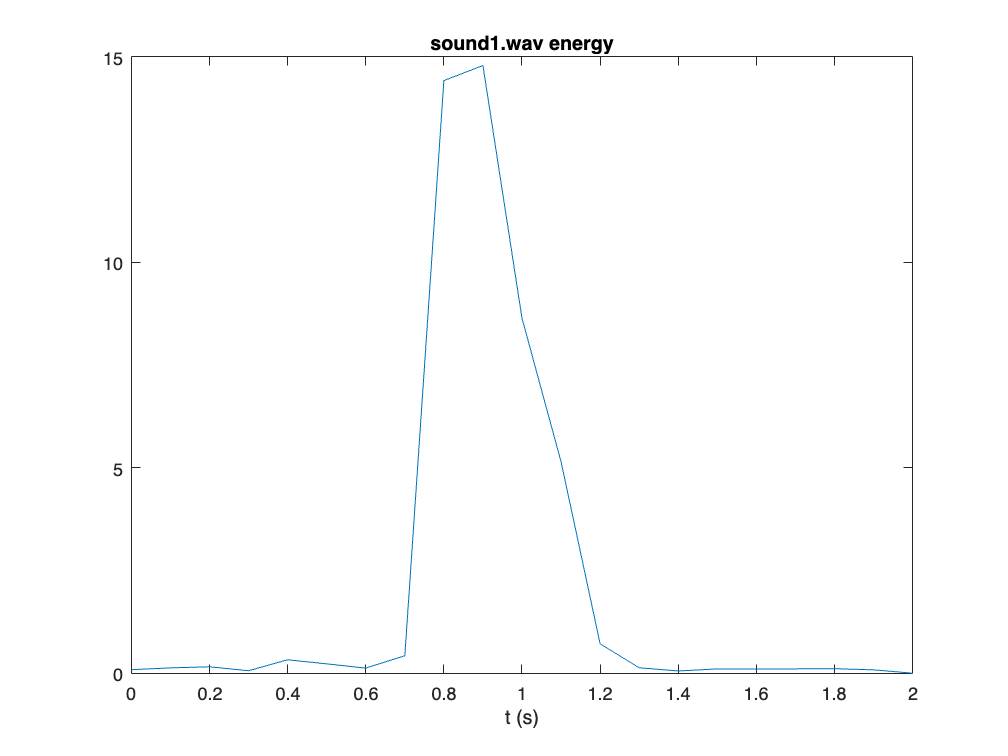

dibuja(E1_frames, 10);
title('sound1.wav energy');

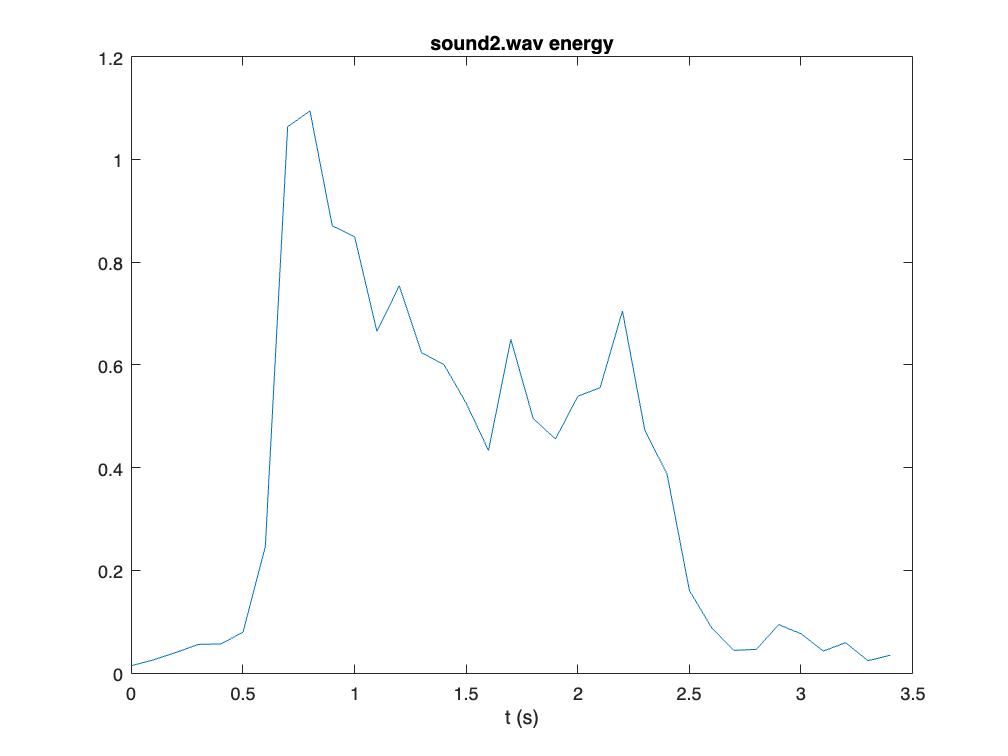

dibuja(E2_frames, 10);
title('sound2.wav energy');

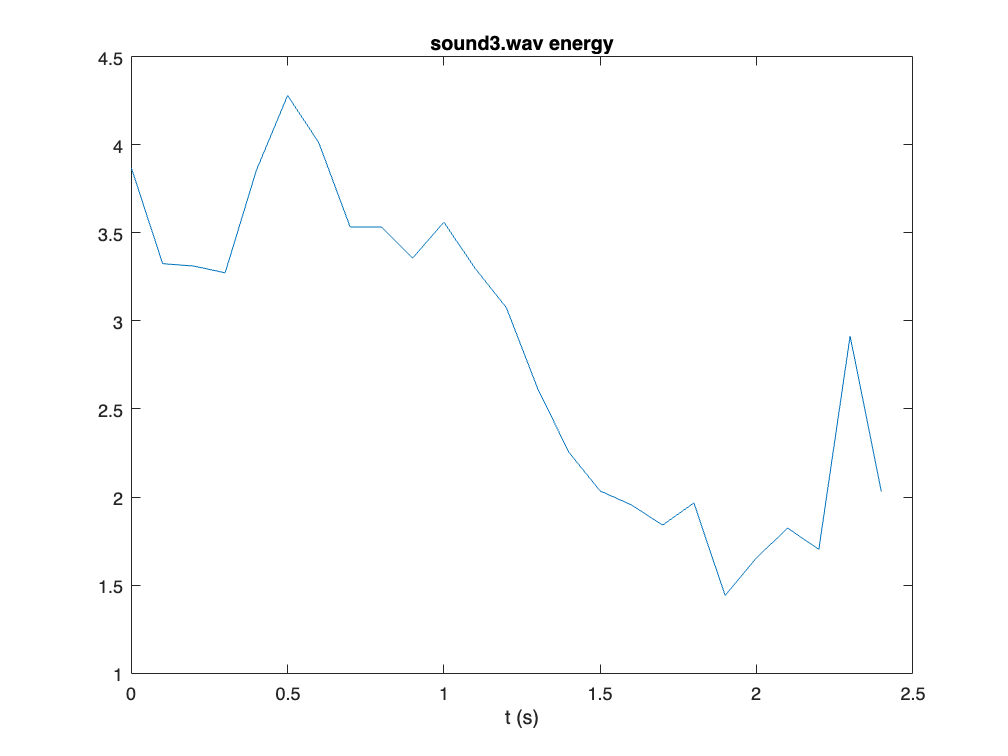

dibuja(E3_frames, 10);
title('sound3.wav energy');

# Ejercicio 1.4

En este ejercicio **vamos a permitir que las tramas tengan solape**. La idea general es que en la trama m-ésima no todas las muestras son nuevas, sino que se seleccionan algunas muestras de la trama anterior (m-1) y el resto son muestras nuevas. En la figura se han seleccionado la mitad (L_frame/2) muestras de la trama anterior y (L_frame/2) muestras nuevas. Se dice entonces que el solape (overlap) es del 50%. 

Para realizar el ejercicio debes realizar previamente una **funcion llamada tramas_con_solape** que descomponga la señal en las tramas con solape. La funcion tiene esta estructura:

El resultado de la funcion es una matriz en el que cada columna contiene las muestras de cada trama. **Escribe al final de este livescript el código de la función.**

Dibuja las energías de las señales y1, y4 e y5 descompuestas con la función anterior en una misma figura con un eje de tiempos continuo. 

Ten en cuenta el salto de tiempos entre tramas que es distinto de cuando usabas la función `tramas_sin_solape`

Comenta las diferencias entre señales.

E1_frames = sum(tramas_con_solape(y1, fs1, 0.02, 0.5) .^ 2)

E1_frames =     0.0080    0.0027    0.0007    0.0051    0.0186    0.0344    0.0404    0.0333    0.0178    0.0086    0.0064    0.0103    0.0130    0.0084    0.0089    0.0220    0.0392    0.0491    0.0621    0.0633    0.0448    0.0198    0.0067    0.0184    0.0374    0.0455    0.0511    0.0418    0.0159    0.0049    0.0092    0.0145    0.0145    0.0110    0.0048    0.0034    0.0111    0.0190    0.0208    0.0211    0.0175    0.0100    0.0246    0.0705    0.1114    0.1243    0.1132    0.0839    0.0599    0.0703


E4_frames = sum(tramas_con_solape(y4, fs4, 0.02, 0.5) .^ 2)

E4_frames =     0.1636    0.1503    0.1509    0.1610    0.1988    0.2033    0.1857    0.1744    0.1508    0.1281    0.1507    0.1476    0.1165    0.1317    0.1333    0.1274    0.1432    0.1242    0.1172    0.1318    0.1113    0.1015    0.1195    0.1899    0.2159    0.1774    0.1571    0.1446    0.1480    0.1977    0.2218    0.1694    0.1143    0.1160    0.1538    0.1866    0.1733    0.1480    0.2508    0.2300    0.1493    0.1682    0.1998    0.2036    0.2920    0.3298    0.2957    0.4018    0.3738    0.2067


E5_frames = sum(tramas_con_solape(y5, fs5, 0.02, 0.5) .^ 2)

E5_frames =     0.0023    0.0011    0.0027    0.0052    0.0058    0.0036    0.0016    0.0016    0.0012    0.0006    0.0003    0.0001    0.0007    0.0034    0.0078    0.0089    0.0054    0.0019    0.0005    0.0011    0.0043    0.0087    0.0101    0.0066    0.0026    0.0010    0.0004    0.0011    0.0030    0.0037    0.0025    0.0015    0.0010    0.0018    0.0040    0.0084    0.0120    0.0106    0.0051    0.0008    0.0005    0.0006    0.0008    0.0013    0.0013    0.0024    0.0059    0.0058    0.0125    0.0152


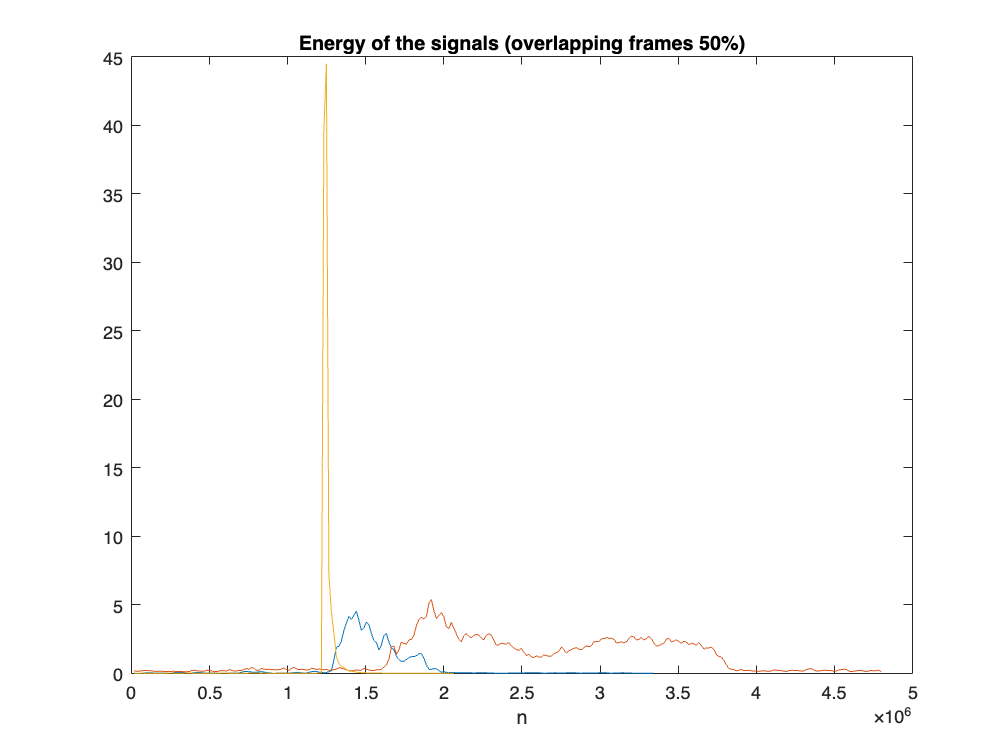

plot((1:length(E1_frames)) * fs1, E1_frames);
hold on
plot((1:length(E4_frames)) * fs4, E4_frames);
plot((1:length(E5_frames)) * fs5, E5_frames);
title('Energy of the signals (overlapping frames 50%)');
xlabel('n');
hold off

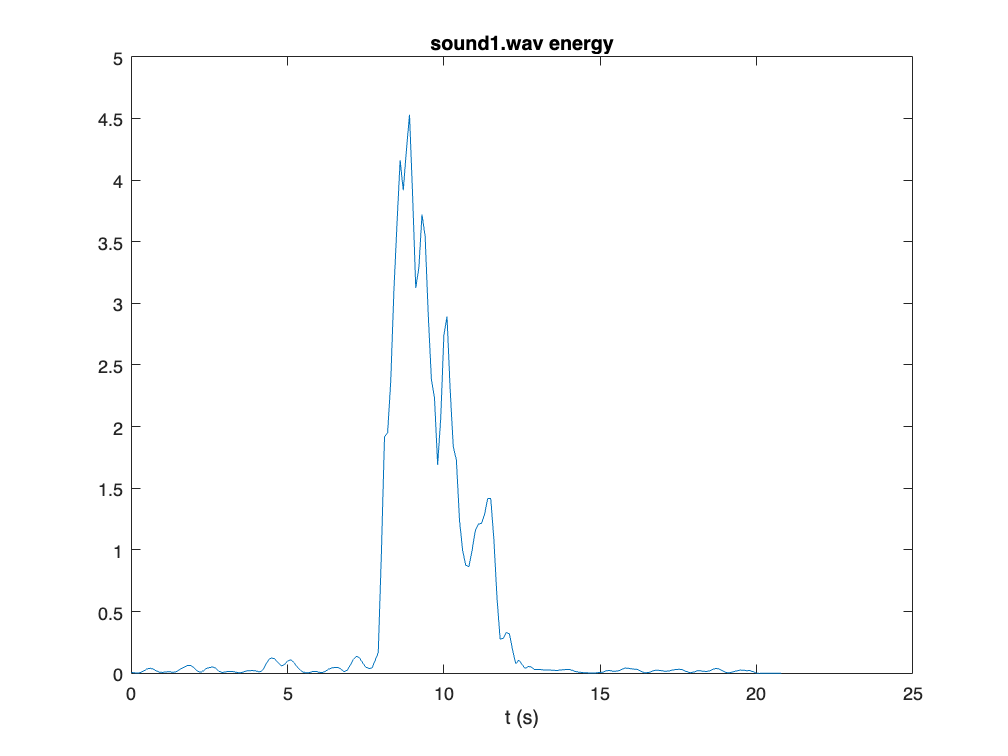

dibuja(E1_frames, 10);
title('sound1.wav energy');

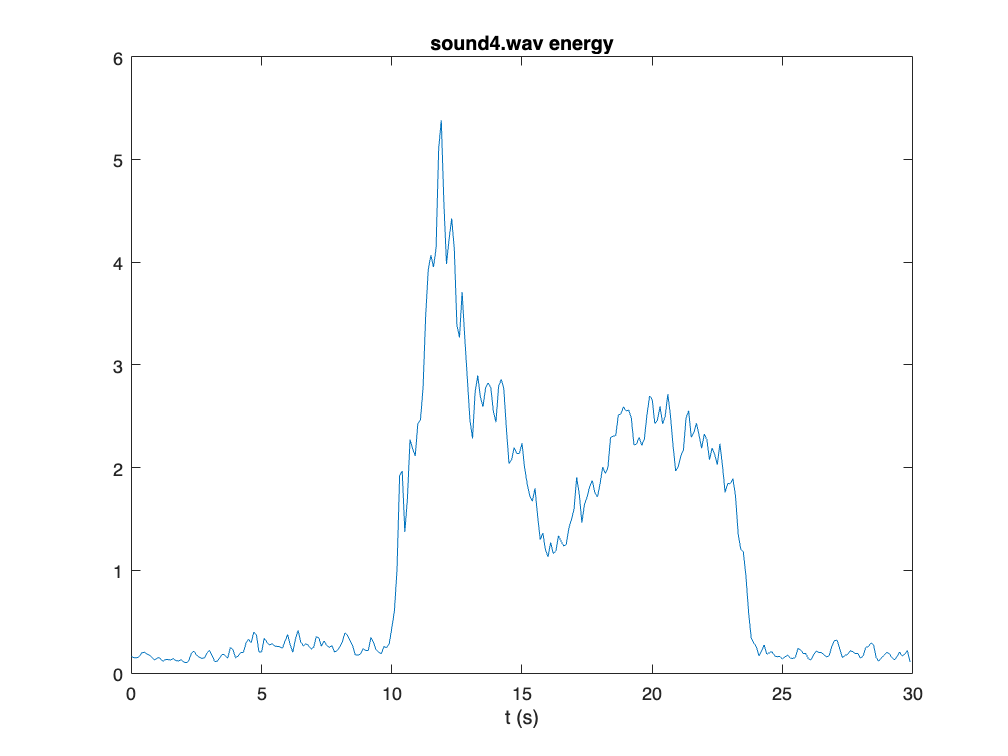

dibuja(E4_frames, 10);
title('sound4.wav energy');

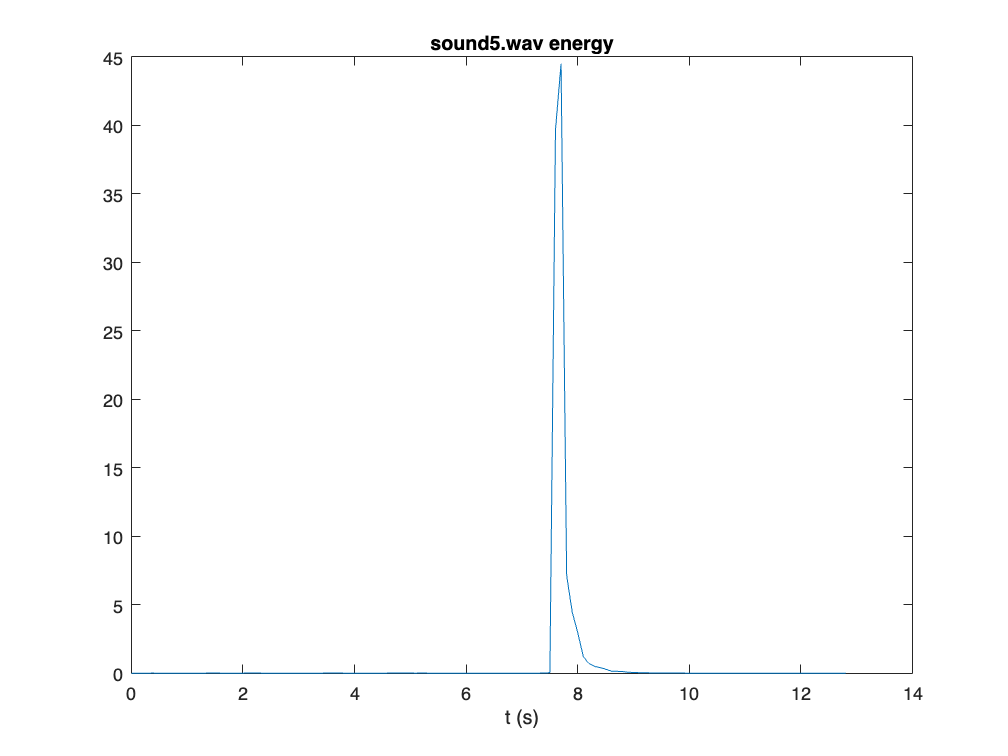

dibuja(E5_frames, 10);
title('sound5.wav energy');

Copia aquí las funciones que te piden en la práctica.

DIBUJA

function dibuja (y1, fs) 
    Ly = length(y1);
    t = (0:Ly-1)/fs;
    plot(t, y1);
    xlabel('t (s)');
end

TRAMAS_SIN_SOLAPE

function Tramas = tramas_sin_solape (x, fs, frame_duration)
    frame_length = round(fs * frame_duration);
    total_frames = floor(length(x) / frame_length);

    x = x(1:total_frames * frame_length);

    Tramas = reshape(x, frame_length, total_frames);
end

TRAMAS_CON_SOLAPE

function Tramas = tramas_con_solape (x, fs, frame_duration, overlap)
    frame_len = round(frame_duration * fs);
    hop_len = round(frame_len * (1 - overlap));
    total_frames = 1 + floor((length(x) - frame_len) / hop_len);

    frames = zeros(frame_len, total_frames);
    for i = 1:total_frames
        start = (i - 1) * hop_len + 1;
        stop = start + frame_len - 1;
        frames(:, i) = x(start:stop);
    end

    Tramas = frames;
end